## Measuring Power

The **periodogram** function computes the signal's FFT and normalizes the output to obtain a power spectral density, PSD, or a power spectrum from which you can measure power. ***The PSD describes how the power of a time signal is distributed with frequency***, it has units of watts/Hz. ***You compute the power spectrum by integrating each point of the PSD over the frequency interval*** at which that point is defined (i.e. over the resolution bandwidth of the PSD). The units of the power spectrum are watts. You can read power values directly from the power spectrum without having to integrate over an interval. Note that ***the PSD and power spectrum are real, so they do not contain any phase information***.

**Measuring Harmonics at the Output of a Non-Linear Power Amplifier**

Load the data measured at the output of a power amplifier that has third order distortion of the form $v_o = v_i + 0.75 v_i^2 + 0.5 v_i^3$, where $v_o$ is the output voltage and $v_i$ is the input voltage. The data was captured with a sample rate of 3.6 kHz. The input $v_i$ consists of a 60 Hz sinusoid with unity amplitude. Due to the nature of the non-linear distortion, you should expect the amplifier output signal to contain a DC component, a 60 Hz component, and second and third harmonics at 120 and 180 Hz.

Load 3600 samples of the amplifier output, compute the power spectrum, and plot the result in a logarithmic scale (decibels-watts or dBW).

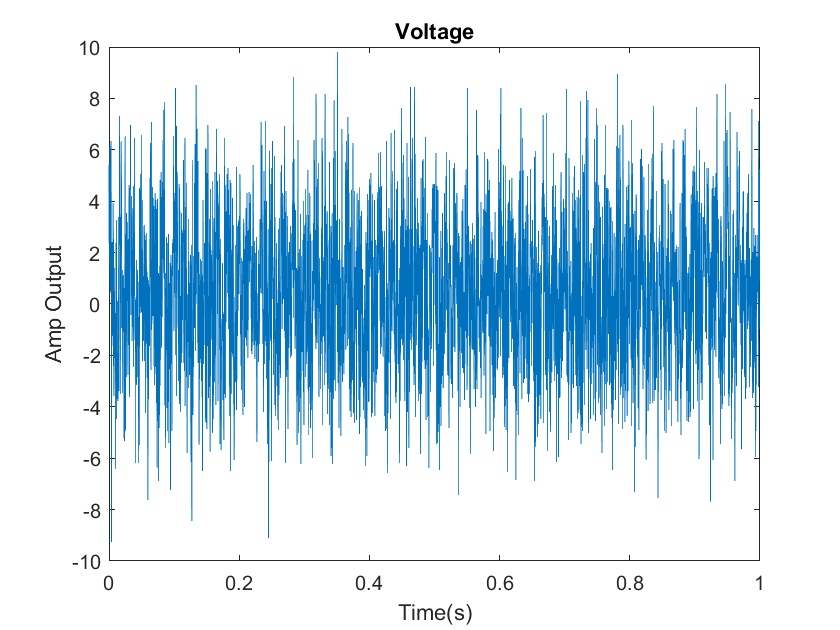

clc
clear
close all

load ampoutput1.mat
Fs = 3600;
NFFT = length(y);
t=0:1/Fs:(1-1/NFFT)*NFFT/Fs;

figure;
plot(t,y);
xlabel('Time(s)');
ylabel('Amp Output')
title('Voltage')

Use **fft** to observe the frequency content of the signal. 

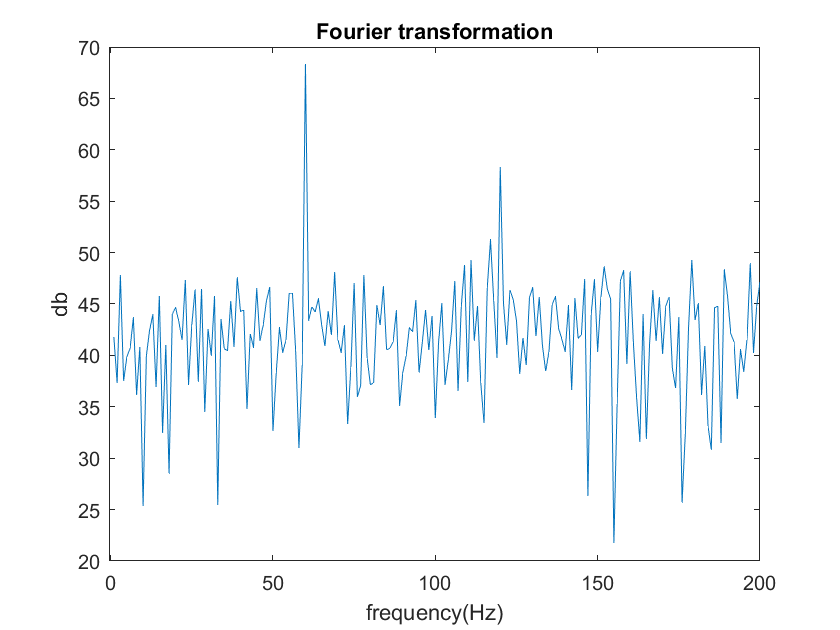

Y=fft(y,NFFT);
ff=(0:1/NFFT:(1/2-1/NFFT))*Fs;
Y(ff>200)=0;
Y(1)=0;
plot(ff,20*log10(abs(Y(1:NFFT/2))));
xlabel('frequency(Hz)')
ylabel('db')
title('Fourier transformation')
xlim([-0.5,200])

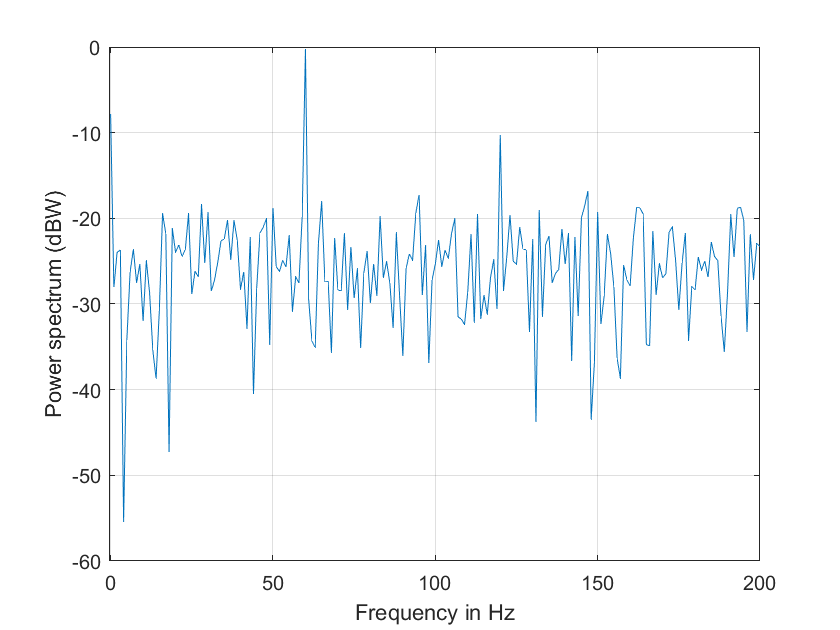

% Power spectrum is computed when you pass a 'power' flag input
[P,F] = periodogram(y,[],NFFT,Fs,'power');   

helperFrequencyAnalysisPlot2(F,10*log10(P),'Frequency in Hz',...
  'Power spectrum (dBW)',[],[],[-0.5 200])

The plot of the power spectrum shows three of the four expected peaks at DC, 60, and 120 Hz. It also shows several more spurious peaks that must be caused by noise in the signal. Note that the 180 Hz harmonic is completely buried in the noise. 

Measure the power of the visible expected peaks:

PdBW = 10*log10(P);
power_at_DC_dBW = PdBW(F==0)   % dBW

power_at_DC_dBW = -8.5627


[peakPowers_dBW, peakFreqIdx] = findpeaks(PdBW,'minpeakheight',-11);
peakFreqs_Hz = F(peakFreqIdx)

peakFreqs_Hz = 60

peakPowers_dBW

peakPowers_dBW = -0.2530

**Improving Power Measurements for Noisy Signals**

As seen on the plot above, the periodogram shows several frequency peaks that are not related to the signal of interest. ***The spectrum looks very noisy. The reason for this is that you only analyzed one short realization of the noisy signal. Repeating the experiment several times and averaging would remove the spurious spectral peaks and yield more accurate power measurements***. You can achieve this averaging using the **pwelch** function. This function will take a large data vector, break it into smaller segments of a specified length, compute as many periodograms as there are segments, and average them. ***As the number of available segments increases, the pwelch function will yield a smoother power spectrum (less variance) with power values closer to the expected values.***

Load a larger observation consisting of 500e3 points of the amplifier output. Keep the number of points used to perform the FFTs as 3600 so that floor(500e3/3600) = 138 FFTs are averaged to obtain the power spectrum.

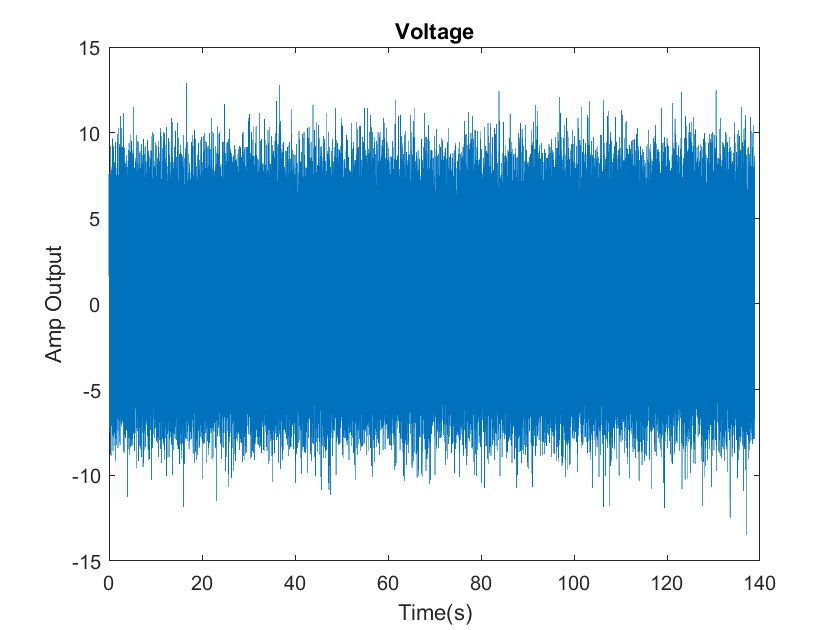

load ampoutput2.mat

NFFT2 = length(y);
t2=0:1/Fs:(1-1/NFFT2)*NFFT2/Fs;

figure;
plot(t2,y);
xlabel('Time(s)');
ylabel('Amp Output')
title('Voltage')

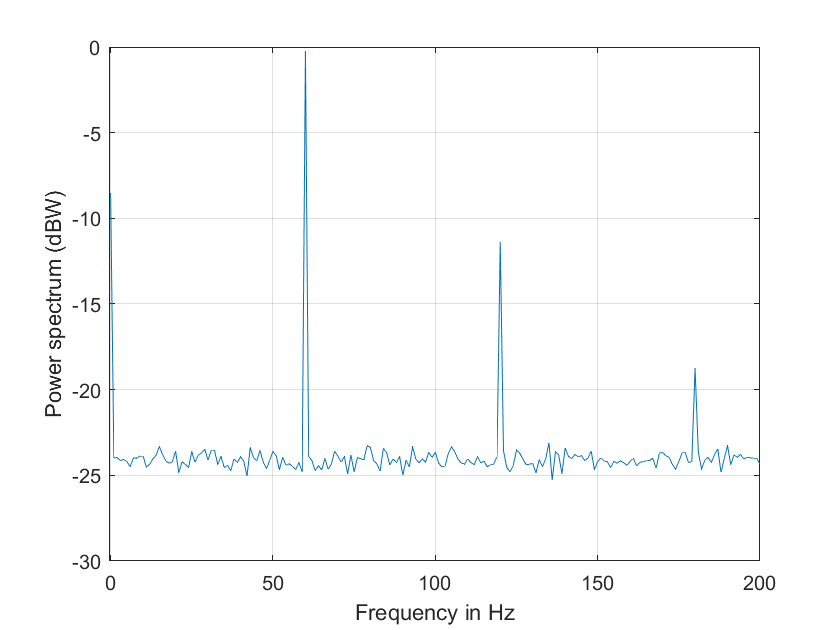

SegmentLength = NFFT; 

% Power spectrum is computed when you pass a 'power' flag input
[P,F] = pwelch(y,ones(SegmentLength,1),0,NFFT,Fs,'power');

helperFrequencyAnalysisPlot2(F,10*log10(P),'Frequency in Hz',...
  'Power spectrum (dBW)',[],[],[-0.5 200])

As seen on the plot, **pwelch** effectively removes all the spurious frequency peaks caused by noise. The spectral component at 180 Hz that was buried in noise is now visible. Averaging removes variance from the spectrum and this effectively yields more accurate power measurements.

**Measuring Total Average Power and Power Over a Frequency Band**

Measuring the total average power of a time-domain signal is an easy and common task. For the amplifier output signal, y, the total average power is computed in the time domain as:

pwr = sum(y.^2)/length(y) % in watts

pwr = 8.1697

In the frequency-domain, the total average power is computed as the sum of the power of all the frequency components of the signal. ***The value of pwr1 consists of the sum of all the frequency components available in the power spectrum of the signal.*** ***The value agrees with the value of pwr computed above using the time domain signal:***

pwr1 = sum(P) % in watts

pwr1 = 8.1698

But what if you wanted to measure the total power available over a band of frequencies? You can use the **bandpower** function to compute the power over any desired frequency band. You can pass the time-domain signal directly as an input to this function to obtain the power over a specified band. In this case, the function will estimate the power spectrum with the periodogram method.

Compute the power over the 50 Hz to 70 Hz band. The result will include the 60 Hz power plus the noise power over the band of interest:

pwr_band = bandpower(y,Fs,[50 70]);
pwr_band_dBW = 10*log10(pwr_band) % dBW

pwr_band_dBW = 0.0341

If you want to control the computation of the power spectrum used to measure the power in a band, you can pass a PSD vector to the **bandpower** function. For instance, you can use the **pwelch** function as you did before to compute the PSD and ensure averaging of the noise effects:

% Power spectral density is computed when you specify the 'psd' option
[PSD,F]  = pwelch(y,ones(SegmentLength,1),0,NFFT,Fs,'psd');
pwr_band1 = bandpower(PSD,F,[50 70],'psd');
pwr_band_dBW1 = 10*log10(pwr_band1) % dBW

pwr_band_dBW1 = 0.0798